clear all;
close all;
clc;

Leitura dados dos arquivos de captura

filename = 'cap2.csv';
filename2 = 'cap2-2.csv';
M = [csvread(filename);
     csvread(filename2)];

Distribuição dos dados na matriz M:

- col 1 = contador

- col 2 = tempo us

- col 3 = azmt_cnt

- col 4 = dist_cnt

- col 5 = amplitude

clear filename filename2;
M(:,1) = M(:,1)+1; % soma 1 para manter o padrão de contador do MATLAB

Variáveis

ligado = true;           % finaliza loop
k = 2;                   % inicio do loop
k_max = size(M,1);       % tamanho max das medicoes
medidas = [];            % vetor para acumulo de alvos
pontos = [];             % vetor para acumulo de indices e qtdd de repeticoes
volta = 1;               % inicializa a volta
load('clutter.mat')      % resgata clutter previamente definido
azmt = M(3,1);           % inicializa azimute

Loop principal

while ligado
    azmt_ant = azmt;
    azmt = M(k,3);
    dist = M(k,4);
    volta_ant = volta;
    
    if azmt < azmt_ant
        volta = volta +1;
    end
    
    idx = [];
    for p=1:size(clutter,1)
        azmt_log = (azmt>=clutter(p,3)-3*clutter(p,2)) & (azmt<=clutter(p,3)+3*clutter(p,2));
        dist_log = (dist>=clutter(p,5)-3*clutter(p,4)) & (dist<=clutter(p,5)+3*clutter(p,4));
        if azmt_log & dist_log
            break
        else
            idx = [idx; p];
        end
    end
    
    if size(idx,1) == p % & size(ind,1) == q
        pontos = [pontos; [M(k,2:end), volta]];
    end
    
    if volta ~= volta_ant
        points = [];
        seq = 0;
        alvos = [];
        for p=1:size(pontos,1)
            azmt_cnt = pontos(p,2);
            dist_cnt = pontos(p,3);
            ind = 0;
            inside = false;
            idx = [];
            for m=1:size(points,1)
                azmt_log = ((azmt_cnt <= points(m,2)+2) & (azmt_cnt >= points(m,2)-2));
                dist_log = ((dist_cnt >= points(m,3)-50) & (dist_cnt <= points(m,3)+50));
                if azmt_log & dist_log
                    inside = true;
                    ind = m;
                else
                    idx = [idx; m];
                end
            end
            
            % Inseri dados na matriz points caso nv dados
            if length(idx) == size(points,1)
                seq = seq+1;
                points = [points; [pontos(p,:) seq]];
            end
            
            % Inseri dados na matriz pt caso dados "repetidos"
            if inside
                points = [points; [pontos(p,:) points(ind,6)]];
            end
        end
        
        count = [1:1:seq]';
        count(:,2) = 0;
        for p=1:size(points,1)
            for m=1:seq
                if m == points(p,6)
                    count(m,2) = count(m,2)+1;
                end
            end
        end
        
        % Aglutinando pontos com maior quantidade de retornos
        for p=1:size(count,1)
            time = []; azmt = []; dist = []; ampl = [];
            for m=1:size(points,1)
                if count(p,1) == points(m,6)
                    time = [time;points(m,1)];
                    azmt = [azmt,points(m,2)];
                    dist = [dist,points(m,3)];
                    ampl = [ampl,points(m,4)];
                end
            end
            time = round(mean(time));
            dp_azmt = round(std(azmt));
            azmt = round(mean(azmt));
            dp_dist = round(std(dist));
            dist = round(mean(dist));
            dp_ampl = round(std(ampl));
            ampl = round(mean(ampl)); 
            alvos = [alvos; [time, dp_azmt, azmt, dp_dist, dist, dp_ampl, ampl, count(p,2), volta_ant]];
        end
        
        ind = [];
        for p=1:size(alvos,1)
            if alvos(p,5) < 14000
                ind = [ind; p];
            end
        end
        alvos = alvos(ind,:);
        
        idx = [];
        for p=1:size(alvos,1)
            if alvos(p,8)<=2 & alvos(p,7)<=25
                idx = [idx; p];
            end
        end
        alvos(idx,:) = [];
        
        medidas = [medidas; alvos];
        pontos = [];
    end
    
    %======================================================================
    % incrementa k
    k = k+1;
    
    % Finaliza loop
    if k == k_max
        ligado = false
    end
end

ligado = logical
   0


Plotando resultados

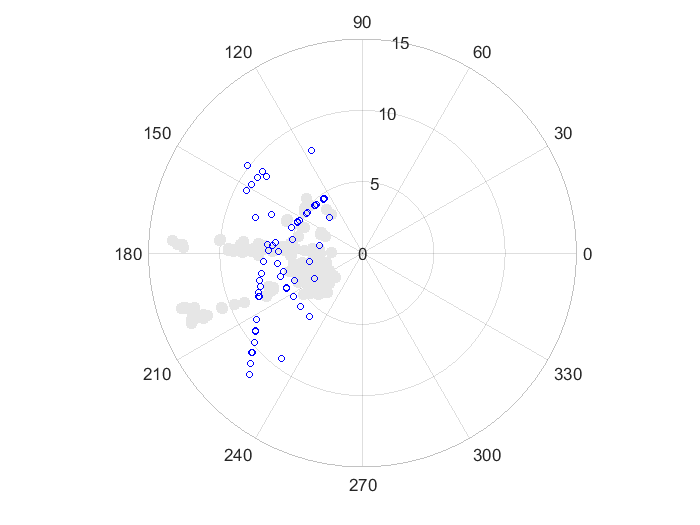

close all
sz = 50; c = [0.9 0.9 0.9]; format = 'o';
polarscatter((clutter(:,3)/3750+0.6)*pi, (clutter(:,5)*0.75+1600)/1000, sz, c, 'filled',format)
hold on
sz = 15; c = [0 0 1]; format = 'o';         
polarscatter((medidas(:,3)/3750+0.6)*pi, (medidas(:,5)*0.75+1600)/1000, sz, c, format)
rlim([0 15])

Salvando os resultados

save('medidas.mat','medidas')


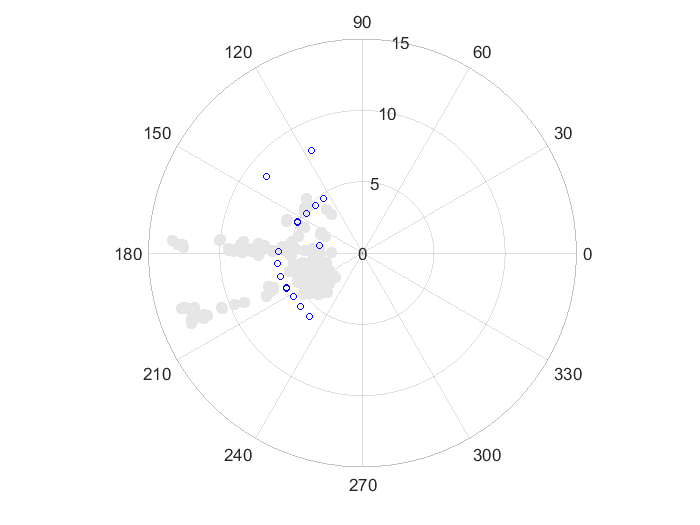

close all
sz = 50; c = [0.9 0.9 0.9]; format = 'o';
polarscatter((clutter(:,3)/3750+0.6)*pi, (clutter(:,5)*0.75+1600)/1000, sz, c, 'filled',format)
rlim([0 15])
hold on
sz = 15; c = [0 0 1]; format = 'o';   

for k=1:size(medidas,1)
    if medidas(k,9) > 13
        break
    end      
    polarscatter((medidas(k,3)/3750+0.6)*pi, (medidas(k,5)*0.75+1600)/1000, sz, c, format)
end

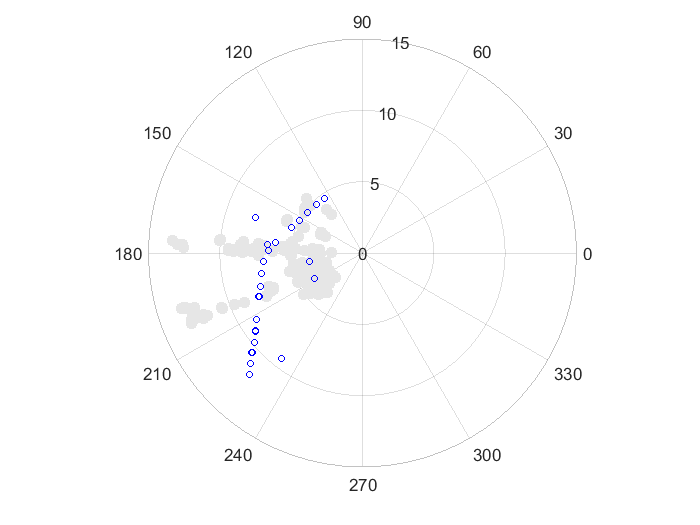

close all
sz = 50; c = [0.9 0.9 0.9]; format = 'o';
polarscatter((clutter(:,3)/3750+0.6)*pi, (clutter(:,5)*0.75+1600)/1000, sz, c, 'filled',format)
rlim([0 15])
hold on
sz = 15; c = [0 0 1]; format = 'o';   

for k=1:size(medidas,1)
    if medidas(k,9) > 29 & medidas(k,9)<60
        polarscatter((medidas(k,3)/3750+0.6)*pi, (medidas(k,5)*0.75+1600)/1000, sz, c, format)
    end      
end

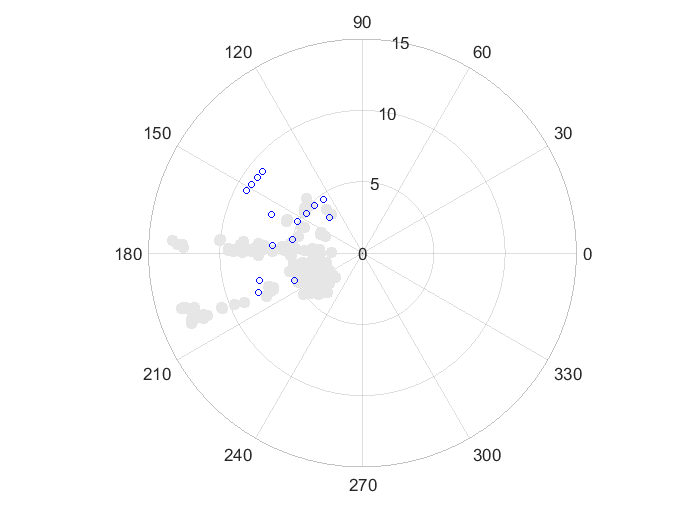

close all
sz = 50; c = [0.9 0.9 0.9]; format = 'o';
polarscatter((clutter(:,3)/3750+0.6)*pi, (clutter(:,5)*0.75+1600)/1000, sz, c, 'filled',format)
rlim([0 15])
hold on
sz = 15; c = [0 0 1]; format = 'o';   

for k=1:size(medidas,1)
    if medidas(k,9) >= 60
        polarscatter((medidas(k,3)/3750+0.6)*pi, (medidas(k,5)*0.75+1600)/1000, sz, c, format)
    end      
end